# Exercise 5: Quantize the network using calibration data

Quantizing a deep neural network in MATLAB® requires calibration by exercising the network to determine the dynamic ranges of its weights, biases, and activations. After calibrating, you can validate the performance of the quantized network and inspect the reduction in size and performance (if any) of the network.

%% Quantize the pretrained network
qLocal = dlquantizer(net, ExecutionEnvironment="MATLAB");
calResults = calibrate(qLocal, xTrain) %#ok<NASGU>

calResults = 56×5 table
    Optimized Layer Name    Network Layer Name    Learnables / Activations     MinValue       MaxValue 
    ____________________    __________________    ________________________    ___________    __________

     "imageinput_Mean"        {'imageinput'}             "Mean"                    832.48        832.48
     "conv_1_Weights"         {'conv_1'    }             "Weights"               -0.85195       0.50554
     "conv_1_Bias"            {'conv_1'    }             "Bias"               -2.7917e-10    2.7709e-10
     "conv_2_Weights"         {'conv_2'    }             "Weights"                -0.4338       0.65112
     "conv_2_Bias"            {'conv_2'    }             "Bias"               -1.9135e-07    2.2121e-07
     "conv_3_Weights"         {'conv_3'    }             "Weights"           

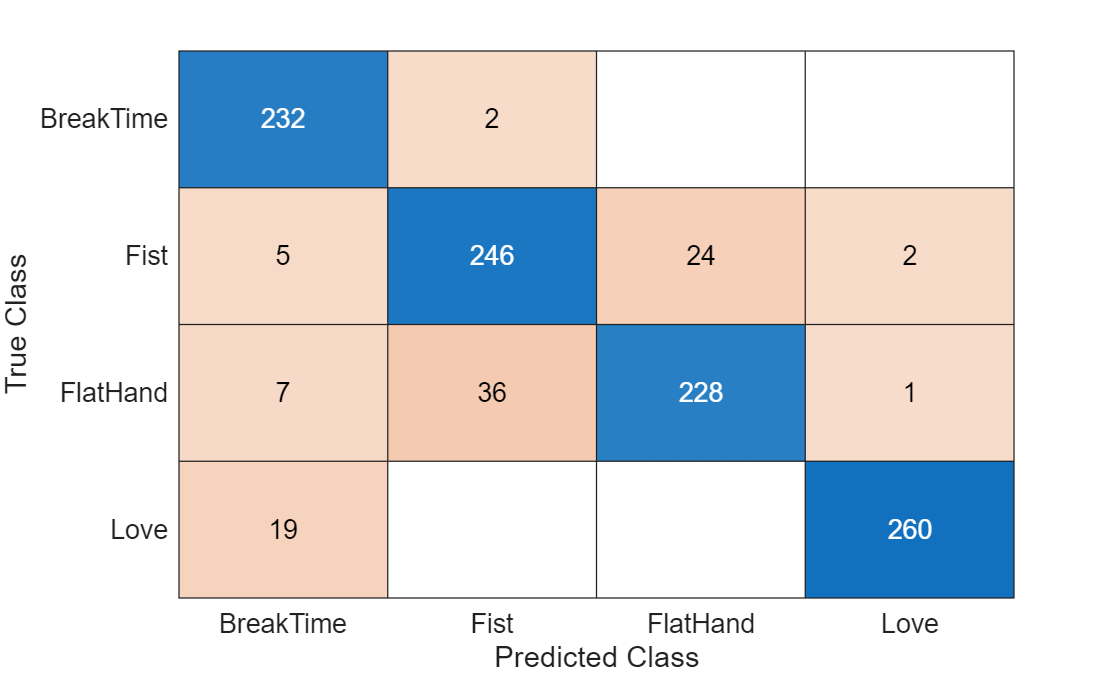

qNet = qLocal.quantize(); 

%% test the Quantized network
scoresQuantized = minibatchpredict(qNet,xTest);
YQuantized = onehotdecode(scoresQuantized,classNames,2);
confusionchart(label_Test,YQuantized);

accuracyQuantized = mean(YQuantized == label_Test) 

accuracyQuantized = 0.9049

## Interactively working with Deep Network Quantizer

deepNetworkQuantizer